# Nonlinear Algebraic Systems

_________________________________________________________________________________________________

# Learning Objectives

By the end of this module, students will be able to

***Solve single nonlinear equations***

- Solve a single nonlinear equation by Picard’s method.

- Solve a single nonlinear equation by Newton’s method.

- Determine whether solving a nonlinear equation by fixed-point method will converge.*

- State the rate of convergence.*

***Solve systems of nonlinear equations***

- Formulate residual equations.

- Input a residual of a system of nonlinear equations in a program.

- Solve a system of nonlinear equations by Newton-Raphson.

***Solve parametric nonlinear systems by continuation methods***

- Solve a parametric nonlinear system using zeroth-order continuation for initial guesses.*

*  Not covered in tutorial

_________________________________________________________________________________________________

## Solving Single Nonlinear Algebra Equations

In this section, we will explore Picard’s method and Newton’s method, which are two traditional methods to systematically solve a single nonlinear algebra equation $f(x)=0$.

## Picard's Method

Picard’s method, which is also known as the method of successive substitution, involves simply adding x to both sides of $f(x)=0$. The iterative scheme is


$$x^{\left(k+1\right)} =f\left(x^{\left(k\right)} \right)+x^{\left(k\right)} \ldotp$$


It is very easy to implement, but it may be very slow to converge.

**Example 1**: Use Picard's method to find the root of function $f(x)=e^{-x}-x$ using initial guess $x^{(0)}=1$.

clear
x0 = 1.0; % initial guess
tol = 1e-5; % convergence tolerance
[x,flag,k] = nonlinear_picard(x0,tol);
fprintf('Picard`s method took %2.0f iterations. The solution is x = %8.6f \n',k,x)

Picard`s method took 20 iterations. The solution is x = 0.567148 


## Newton's Method

Newton’s method is the most common method for solving a single nonlinear equation. The iterative scheme is

$x^{(k+1)}=x^{(k)}- \frac{f(x^{(k)})}{f'(x^{(k)})} $.

As indicated by the scheme, the derivative $f'(x)$ is required for iterations.

In order to solve **Example 1** using Newton's method, we should derive the derivative term $f'(x)=-e^{-x}-1$.

clear
x0 = 1.0; % initial guess
tol = 1e-5; % convergence tolerance
[x,flag,k] = nonlinear_newton(x0,tol);
fprintf('Newton`s method took %2.0f iterations. The solution is x = %8.6f \n',k,x)

Newton`s method took  3 iterations. The solution is x = 0.567143 


Netwon's method exhibits quadratic convergence, that is a huge advantage, as the convergence accelerates rapidly near the solution.

## Solving Systems of Nonlinear Algebra Equations

In this section, we introduce the numerical methods to solve systems of nonlinear algebra equations. The general form is given by:


$$R_1(x_1,x_2,\ldots,x_n)=0\\
R_2(x_1,x_2,\ldots,x_n)=0\\
\ \ \ \ \ \ \  \vdots\\
R_n(x_1,x_2,\ldots,x_n)=0

$$


We need to be careful to write the equations in a form such that they are equal to zero in order to apply the fixed-point methods. The compact notation of the system of nonlinear equations is $\bf R(\bf x)=\bf0$, with $\bf x$ being the vector of unknowns as $\mathbf x = (x_1,x_2,\ldots,x_n)$, and 


$$\mathbf{R}=\left\lbrack \begin{array}{c}
R_1 \left(x_1 ,x_2 ,\ldots,x_n \right)\\
R_2 \left(x_1 ,x_2 ,\ldots,x_n \right)\\
\vdots \\
R_n \left(x_1 ,x_2 ,\ldots,x_n \right)
\end{array}\right\rbrack$$


a vector-valued function which we will refer to as the **residual**.

## Newton-Raphson

A common method for solving nonlinear systems of equations is the Newton–Raphson method. It relies on the same idea as Newton’s method but is now generalized to n dimensions. The iterative scheme is given by

$\mathbf{J}(\mathbf{x}^{(k)})(\mathbf{x}^{(k+1)}-\mathbf{x}^{(k)})=-\mathbf{R}(\mathbf{x}^{(k)})$,

where the $\mathbf J$ is the Jacobian matrix defined as

$\mathbf{J}=\left\lbrack \begin{array}{ccc}
\frac{\partial R_1 }{\partial x_1 } & \ldots & \frac{\partial R_1 }{\partial x_n }\\
\vdots  & \ddots  & \vdots \\
\frac{\partial R_n }{\partial x_1 } & \ldots & \frac{\partial R_n }{\partial x_n }
\end{array}\right\rbrack$,

that is to be evaluated at the value $
\mathbf{x}^{(k)}$. In component form, the elements of the Jacobian are the partial derivatives $J_{ij}=\frac{\partial R_i}{\partial x_j}$.

It is common to use a shorthand notation $\mathbf{\delta}^{(k+1)}=\mathbf{x}^{(k+1)}-\mathbf{x}^{(k)}$ for the difference between the previous values and the new values of $\mathbf x$. The iterative

scheme then becomes the linear system


$$\mathbf{J}(\mathbf{x}^{(k)})(\mathbf{\delta}^{(k+1)})=-\mathbf{R}(\mathbf{x}^{(k)})$$


$\mathbf x^{(k+1)}:=\mathbf x^{(k)}+\mathbf{\delta}^{(k+1)}$.

We have reduced solving the system of nonlinear equations into an iterative method where, at each step, we need to solve a system of linear equations. Since $\mathbf{x}^{(k)}$ changes at each time step, we need to solve the linear system for different right-hand-side constant vectors and Jacobian matrices.

The implementation of this method goes through the following steps.

- Create a vector with the residuals.

- Compute the elements in the Jacobian. 

- Pick an initial guess $\mathbf{x}^{(0)}$.

- Iterate until either $\| \mathbf R \|$ and/or $\|\mathbf \delta\|$ are small.

**Example 2**: Use Netwon-Raphson to find the root of the system of equations


$$f_1(x_1,x_2)=e^{-x_1}-x_2\\
f_2(x_1,x_2)=x_1+x_2^2-3x_2$$


using the initial guess $x_1^{(0)}=0$ and $x_2^{(0)}=0$.

**Solution:**

The residual vector for this problem is


$$\mathbf{R}=\left\lbrack \begin{array}{c}
e^{-x_1 } -x_2 \\
x_1 +x_2^2 -3x_2 
\end{array}\right\rbrack$$


If we take the logical choice for the vector of unknowns to be $\mathbf x =(x_1,x_2)$, then the Jacobian is


$$\mathbf{J}=\left\lbrack \begin{array}{cc}
-e^{-x_1 }  & -1\\
1 & {2x}_2 -3
\end{array}\right\rbrack$$


Then, we implement the iterative algorithm by:

x0 = [0.0;0.0]; % initial guess
tol = 1e-5; % convergence tolerance
[x,flag,k] = nonlinear_newton_raphson_E2(x0,tol);
fprintf('Newton-Raphson took %3.0f iterations. The solution is x1 = %8.6f and x2 = %8.6f \n',k,x(1), x(2))

Newton-Raphson took   4 iterations. The solution is x1 = 0.982753 and x2 = 0.374279 


## Case Study: Reactor-Separator-Recycle Process for Chlorination of Benzene

In this section, we consider a reactor-separator-recycle process for chlorination of benzene as illustrated in the following figure:

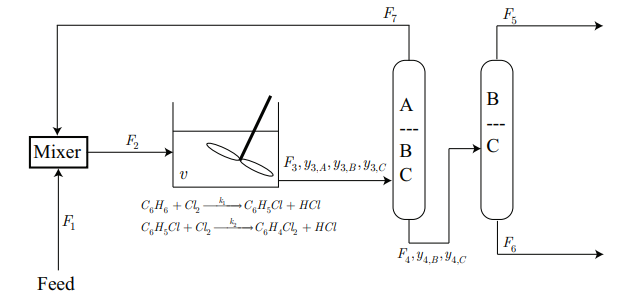

In the continuous stirred-tank reactor (CSTR), benzene $\text C_6 \text H_6$ (A) reacts with chlorine $\text{Cl}_2$ to yield monochlorobenzene $\text C_6 \text H_5 \text{Cl}$ (B) and dichlorobenzene $\text C_6 \text H_4 \text{Cl}_2$ (C). The chlorine $\text{Cl}_2$ is in excess, thus the reactions can be simplified as:


$$\begin{array}{l}
A\overset{k_1 }{\longrightarrow} B\\
B\overset{k_2 }{\longrightarrow} C
\end{array}$$


The reaction rates are given by:


$$r_1=k_1 \frac{y_{3,A}}{y_{3,A} \hat v_A + y_{3,B} \hat v_B + y_{3,C} \hat v_C},\\
r_2 =k_2 \frac{y_{3,B}}{y_{3,A} \hat v_A + y_{3,B} \hat v_B + y_{3,C} \hat v_C}.$$


The reactor volume is $v=6 \text m^3$, the reaction rate constants are $k_1=0.4\text h^{-1}$ and $k_2 = 0.055 \text h^{-1}$, and the specific volumes of each species are $\hat v_A=8.937\times10^{-2} \text m^3/\text{kmol}$, $\hat v_B=1.018\times10^{-1} \text m^3/\text{kmol}$, and $\hat v_C=1.130\times10^{-1}\text m^3/\text{kmol}$. 

The purporse is to produce $50 \text{kmol}$ per hour in the outlet stream of the final separator ($F_5=50 \text{kmol/h}$) and we now want to solve for **the mole fractions of each species** ($y_{3,A}$,$y_{3,B}$, and $y_{3,C}$) in the stream $F_3$.

To solve this problem, we analyze the degrees of freedom for this system:

- Unknowns: $F_1,F_2,F_3,F_4,F_5,F_6,F_7,y_{3,A},y_{3,B},y_{3,C},y_{4,B},y_{4,C},k_1,k_2,\hat v_A, \hat v_B, \hat v_C, v$

- Process specifications: $F_5,k_1,k_2,\hat v_A, \hat v_B, \hat v_C, v$

- Degrees of freedom: 18 unkowns - 7 specifications = 11 degrees of freedom

Thus, 11 independent equations are required for solving the system. Based on the conservation of mass, we can set up the system of equations:

- Mixer:


$$F_1+F_7=F_2$$


- Reactor:


$$F_2-r_1v=y_{3,A} F_3\\
0=(r_1-r_2)v+y_{3,B} F_3\\
0=r_2v - y_{3,C}F_3$$


- Separator 1: 


$$F_3=F_4+F_7\\
y_{3,B}F_3=y_{4,B}F_4\\
y_{3,C}F_3=y_{4,C}F_4$$


- Separator 2:


$$F_4=F_5+F_6\\
y_{4,B}F_4=F_5$$


- Other Relationships:


$$y_{3,A}+y_{3,B}+y_{3,C}=1\\
y_{4,B}+y_{4,C}=1$$


Since the compositions are unknown and the reaction rate laws are complex, the system is nonlinear.

## Solutions:

To solve a nonlinear system of equations, we can use the Newton-Raphson method.  The 11 independent equations should be written in residual form by moving every term to one side:


$$\begin{array}{l}
F_1 -F_2 +F_7 =0\\
\begin{array}{l}
F_2 -\frac{k_1 y_{3,A} }{y_{3,A} {\hat{v} }_A +y_{3,B} {\hat{v} }_B +y_{3,C} {\hat{v} }_C }v-y_{3,A} F_3 =0\\
\frac{{k_2 y_{3,B} -k}_1 y_{3,A} }{y_{3,A} {\hat{v} }_A +y_{3,B} {\hat{v} }_B +y_{3,C} {\hat{v} }_C }v+y_{3,B} F_3 =0\\
\frac{{k_2 y}_{3,B} }{y_{3,A} {\hat{v} }_A +y_{3,B} {\hat{v} }_B +y_{3,C} {\hat{v} }_C }v-y_{3,C} F_3 =0
\end{array}\\
\begin{array}{l}
F_3 -F_4 -F_7 =0\\
y_{3,B} F_3 -y_{4,B} F_4 =0\\
y_{3,C} F_3 -y_{4,C} F_4 =0
\end{array}\\
\begin{array}{l}
F_4 -F_5 -F_6 =0\\
y_{4,B} F_4 -F_5 =0
\end{array}\\
\begin{array}{l}
y_{3,A} +y_{3,B} +y_{3,C} -1=0\\
y_{4,B} +y_{4,C} -1=0
\end{array}
\end{array}$$


We define the variable vector for this problem as  $\mathbf x=(F_1,F_2,y_{3,A},y_{3,B},y_{3,C},F_3,y_{4,B},y_{4,C},F_4,F_6,F_7)$, then the residual vector is constructed as:


$$\mathbf{R}\left(\mathbf{x}\right)=\left\lbrack \begin{array}{l}
x_1 -x_2 +x_{11} \\
x_2 -\frac{k_1 x_3 v}{x_3 \hat{\;v_A } +x_4 \hat{\;v_B } +x_5 \hat{\;v_C } }-x_3 x_6 \\
\frac{\left({k_2 x_4 -k}_1 x_3 \right)v}{x_3 \hat{\;v_A } +x_4 \hat{\;v_B } +x_5 \hat{\;v_C } }+x_4 x_6 \\
\frac{k_2 x_4 v}{x_3 \hat{\;v_A } +x_4 \hat{\;v_B } +x_5 \hat{\;v_C } }+x_5 x_6 \\
x_6 -x_9 -x_{11} \\
x_4 x_6 -x_7 x_9 \\
x_5 x_6 -x_8 x_9 \\
x_9 -F_5 -x_{10} \\
x_7 x_9 -F_5 \\
x_3 +x_4 +x_5 -1\\
x_7 +x_8 -1
\end{array}\right\rbrack =\mathbf{0}$$


Then, we form the Jacobian as:


$$\mathbf{J}\left(\mathbf{x}\right)=\left\lbrack \begin{array}{ccc}
\frac{\partial R_1 }{\partial x_1 } & \ldots & \frac{\partial R_1 }{\partial x_{11} }\\
\vdots  & \ddots  & \vdots \\
\frac{\partial R_{11} }{\partial x_1 } & \ldots & \frac{\partial R_{11} }{\partial x_{11} }
\end{array}\right\rbrack$$


Most entries in the Jacobian are zero, the non-zero entries are indicated in the code below. Then, we implement the Newton-Raphson algorithm by:

%clear all
x = [35.7; 357; 0.9; 0.07; 0.03; 357; 0.7; 0.3; 35.7; 10.7; 321.3]; % initial guess
% x = [F1; F2;  y3a; y3b;  y3c;  F3;  y4b; y4c; F4;   F6;   F7]
tol = 1e-4; % convergence tolerance
[x,flag,k] = nonlinear_newton_raphson(x,tol); % call Newton-Raphson function
fprintf('Newton-Raphson took %3.0f iterations.\n The mole fraction of each species are \n y_{3,A} = %8.6f\n y_{3,B} = %8.6f\n y_{3,C} = %8.6f',k,x(3),x(4),x(5))

Newton-Raphson took   4 iterations.
 The mole fraction of each species are 
 y_{3,A} = 0.945483
 y_{3,B} = 0.054088
 y_{3,C} = 0.000429

All the functions used within the above code are defined below:

Picard's method for **Example 1** is defined as follows:

function [x,flag,k] = nonlinear_picard(x,tol)
% x = initial guess for x
% tol = criteria for convergence
% requires function f = getf(x)
% flag = 0 if failed, 1 if converged
f = getf(x);
k = 0; % counter
kmax = 20; % max number of iterations allowed
while abs(f) > tol
    x = x + f; % Picard’s method
    k = k + 1; % update counter
    f = getf(x); % f(x) for while loop and counter
    if k > kmax
        fprintf('Did not converge.\n')
        break
    end
end
if k > kmax || x == Inf || x == -Inf
    flag = 0;
else
    flag = 1;
end
end

Netwon's method for **Example 1** is defined as follows:

function [x,flag,k] = nonlinear_newton(x,tol)
% x = initial guess for x
% tol = criteria for convergence
% requires function f = getf(x) and df = getdf(x)
% flag = 0 if failed, 1 if converged
f = getf(x);
k = 0; % counter
kmax = 20; % max number of iterations allowed
while abs(f) > tol
    df = getdf(x);
    x = x - f/df; % Newton’ĂŹs method
    k = k + 1; % update counter
    f = getf(x); % f for while loop and counter
    if k > kmax
        fprintf('Did not converge.\n')
        break
    end
end
if k > kmax || x == Inf || x == -Inf
    flag = 0;
else
    flag = 1;
end
end

$f(x)$ for **Example 1** is given by:

function f = getf(x)
f = exp(-x)- x;
end

$f'(x)$ for **Example 1** is given by:

function df = getdf(x)
df = -exp(-x) - 1;
end

Newton-Raphson for **Example 2** is defined as follows:

function [x,flag,k] = nonlinear_newton_raphson_E2(x,tol)
% x = initial guess for x
% tol = criteria for convergence
% requires function R = getR(x)
% requires function J = getJ(x)
% flag = 0 if failed, 1 if converged
R = getR_E2(x);
k = 0; % counter
kmax = 100; % max number of iterations allowed
while norm(R) > tol
    J = getJ_E2(x); % c ompute Jacobian
    del = -J\R; % Newton Raphson
    x = x + del; % update x
    k = k + 1; % u pdate counter
    R = getR_E2(x); % f for while loop and counter
    if k > kmax
        fprintf('Did not converge.\n')
        break
    end
end
if k > kmax || max(x) == Inf || min(x) == -Inf
    flag = 0;
else
    flag = 1;
end
end

The residual function for **Example 2** is given by:

function R = getR_E2(x)
R = zeros(2,1);
R(1) = exp(-x(1)) - x(2);
R(2) = x(1) + x(2)^2 -3*x(2);
end

The Jacobian function for **Example 2** is given by:

function J = getJ_E2(x)
J = zeros(2);
J(1,1) = -exp(-x(1));
J(1,2) = -1;
J(2,1) = 1;
J(2,2) = 2*x(2) - 3;
end

Newton-Raphson for **Case Study** is defined as follows:

function [x,flag,k] = nonlinear_newton_raphson(x,tol)
% x = initial guess for x
% tol = criteria for convergence
% requires function R = getR(x)
% requires function J = getJ(x)
% flag = 0 if failed, 1 if converged
R = getR(x);
k = 0; % counter
kmax = 100; % max number of iterations allowed
while norm(R) > tol
    J = getJ(x); % c ompute Jacobian
    del = -J\R; % Newton Raphson
    x = x + del; % update x
    k = k + 1; % u pdate counter
    R = getR(x); % f for while loop and counter
    if k > kmax
        fprintf('Did not converge.\n')
        break
    end
end
if k > kmax || max(x) == Inf || min(x) == -Inf
    flag = 0;
else
    flag = 1;
end
end

The residual function for the **Case Study** is given by:

function R = getR(x)
% process specifications and constants
V = 6; % m^3
F5 = 25; % kmol/h
Va = 8.937e-2; % m^3/kmol
Vb = 1.018e-1; % m^3/kmol
Vc = 1.13e-1; % m^3/kmol
k1 = 0.4; % h^-1
k2 = 0.055; % h^-1

% residual formulation
R = zeros(11,1);

% x1 - x2 + x11 = 0
R(1) = x(1) - x(2) + x(11);

% x2 - k1*x3*v/(x3*Va + x4*Vb + x5*Vc) - x3*x6 = 0
R(2) = x(2) - k1*x(3)*V/(x(3)*Va + x(4)*Vb + x(5)*Vc) - x(3)*x(6);

% (k2*x4 - k1*x3)*v/(x3*Va + x4*Vb + x5*Vc) + x4*x6 = 0
R(3) = (k2*x(4) - k1*x(3))*V/(x(3)*Va + x(4)*Vb + x(5)*Vc) + x(4)*x(6);

% k2*x4*v/(x3*Va + x4*Vb + x5*Vc) - x5*x6 = 0
R(4) = k2*x(4)*V/(x(3)*Va + x(4)*Vb + x(5)*Vc) - x(5)*x(6);

% x6 - x9 - x11 = 0
R(5) = x(6) - x(9) - x(11);

% x4*x6 - x7*x9 = 0
R(6) = x(4)*x(6) - x(7)*x(9);

% x5*x6 - x8*x9 = 0
R(7) = x(5)*x(6) - x(8)*x(9);

% x9 - F5 - x10 = 0
R(8) = x(9) - F5 - x(10);

% x7*x9 - F5 = 0
R(9) = x(7)*x(9) - F5;

% x3 + x4 + x5 - 1 = 0
R(10) = x(3) + x(4) + x(5) - 1;

% x7 + x8 - 1 = 0
R(11) = x(7) + x(8) - 1;
end

The Jacobian function for the **Case Study** is given by:

function J = getJ(x)
% process specifications and constants
V = 6; % m^3
F5 = 25; % kmol/h
Va = 8.937e-2; % m^3/kmol
Vb = 1.018e-1; % m^3/kmol
Vc = 1.13e-1; % m^3/kmol
k1 = 0.4; % h^-1
k2 = 0.055; % h^-1

% Jacobian formulation
J = zeros(11);

% dR1/dx1
J(1,1) = 1;

% dR1/dx2
J(1,2) = -1;

% dR1/dx11
J(1,11) = 1;

% dR2/dx2
J(2,2) = 1;

% dR2/dx3
J(2,3) = -(k1*V*(x(3)*Va + x(4)*Vb + x(5)*Vc) - k1*x(3)*V*Va)/(x(3)*Va + x(4)*Vb + x(5)*Vc)^2 - x(6);

% dR2/dx4
J(2,4) = k1*x(3)*V*Vb/(x(3)*Va + x(4)*Vb + x(5)*Vc)^2;

% dR2/dx5
J(2,5) = k1*x(3)*V*Vc/(x(3)*Va + x(4)*Vb + x(5)*Vc)^2;

% dR2/dx6
J(2,6) = -x(3);

% dR3/dx3
J(3,3) = (-k1*V*(x(3)*Va + x(4)*Vb + x(5)*Vc) - (k2*x(4) - k1*x(3))*V*Va)/(x(3)*Va + x(4)*Vb + x(5)*Vc)^2;

% dR3/dx4
J(3,4) = (k2*V*(x(3)*Va + x(4)*Vb + x(5)*Vc) - (k2*x(4) - k1*x(3))*V*Vb)/(x(3)*Va + x(4)*Vb + x(5)*Vc)^2 + x(6);

% dR3/dx5
J(3,5) = -(k2*x(4) - k1*x(3))*V*Vc/(x(3)*Va + x(4)*Vb + x(5)*Vc)^2;

% dR3/dx6
J(3,6) = x(4);

% dR4/dx3
J(4,3) = -k2*x(4)*V*Va/(x(3)*Va + x(4)*Vb + x(5)*Vc)^2;

% dR4/dx4
J(4,4) = (k2*V*(x(3)*Va + x(4)*Vb + x(5)*Vc) - k2*x(4)*V*Vb)/(x(3)*Va + x(4)*Vb + x(5)*Vc)^2 ;

% dR4/dx5
J(4,5) = -k2*x(4)*V*Vc/(x(3)*Va + x(4)*Vb + x(5)*Vc)^2 - x(6);

% dR4/dx6
J(4,6) = -x(5);

% dR5/dx6
J(5,6) = 1;

% dR5/dx9
J(5,9) = -1;

% dR5/dx11
J(5,11) = -1;

% dR6/dx4
J(6,4) = x(6);

% dR6/dx6
J(6,6) = x(4);

% dR6/dx7
J(6,7) = -x(9);

% dR6/dx9
J(6,9) = -x(7);

% dR7/dx5
J(7,5) = x(6);

% dR7/dx6
J(7,6) = x(5);

% dR7/dx8
J(7,8) = -x(9);

% dR7/dx9
J(7,9) = -x(8);

% dR8/dx9
J(8,9) = 1;

% dR8/dx10
J(8,10) = -1;

% dR9/dx7
J(9,7) = x(9);

% dR9/dx9
J(9,9) = x(7);

% dR10/dx3
J(10,3) = 1;

% dR10/dx4
J(10,4) = 1;

% dR10/dx5
J(10,5) = 1;

% dR11/dx7
J(11,7) = 1;

% dR11/dx8
J(11,8) = 1;
end